# **Experimental Evaluation of Single-Carrier Alamouti System**

The code below uses the DSP associated with the single-carrier Alamouti system to recover transmitted symbols in 16-QAM

% Setup
clearvars
addpath ExperimentalDataBence

% The experimental data used here has already been matched filtered and has
% been downconverted to baseband

load('exp_data_1e-2.mat');

% CD compensation
SpS = 2;
Rs=50e9;
linkLength = 25e3;
D = 17;
CLambda = 1550e-9;
c = 299792458; % Speed of light in m/s

N_CD = ceil(6.67*(D*1e-6)*(CLambda^2)*linkLength*(Rs^2)*SpS/(2*pi*c)) % CD Equalizer Length

N_CD = 19

N_FFT = 2^10

N_FFT = 1024

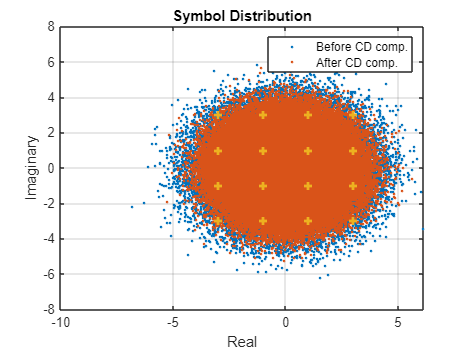


signal_CDC = OverlapSaveCDC(ux.', D, linkLength, CLambda, Rs, 1, SpS, N_FFT, N_CD);

% Visualising symbol distribution
plot(ux, '.');
hold on
title("Symbol Distribution")
plot(signal_CDC, '.');
plot(s_qam, '+', LineWidth=2);
xlabel("Real")
ylabel("Imaginary")
legend("Before CD comp.", "After CD comp.")
grid on
hold off

% Adaptive Equalization
% NTaps = 60; NRemoveF = 25000; NRemoveB = 6000; N1 = 16000; Mu_T = 1e-4; Mu_DD = Mu_T; Mu_p=2e-2;
NTaps = 180; NRemoveF = 25000; NRemoveB = 6000; N1 = 16000; Mu_T = 2e-4; Mu_DD = Mu_T; Mu_p=2e-2;

trainSymbs = s_qam;
[equalizedSymbs, pQAM, w11QAM, w12QAM, w21QAM, w22QAM, errQAM] = AdapEqualizerAlamouti(signal_CDC, trainSymbs, SpS, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM'); % Shaped

% Visualising filter variable evolution
plot([1:size(pQAM)], w11QAM', '-');

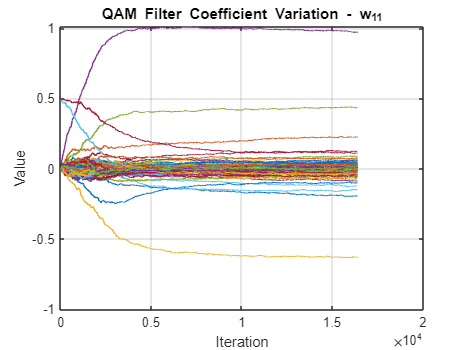

title("QAM Filter Coefficient Variation - w_{11}")
xlabel("Iteration")
ylabel("Value")
grid on


plot([1:size(pQAM)], w12QAM', '-');

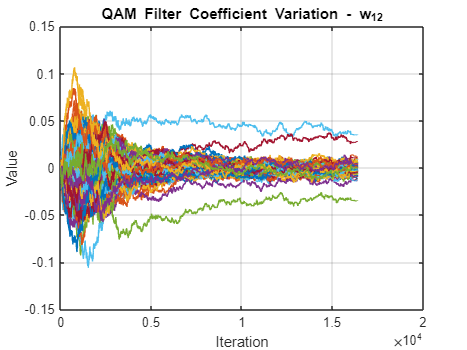

title("QAM Filter Coefficient Variation - w_{12}")
xlabel("Iteration")
ylabel("Value")
grid on


plot([1:size(pQAM)], w21QAM', '-');

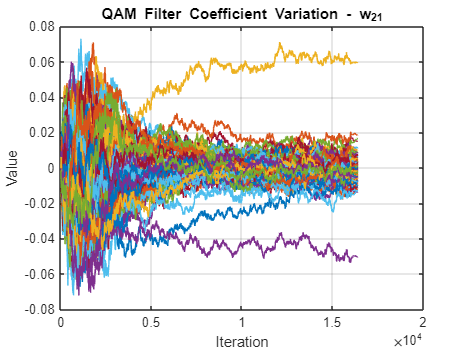

title("QAM Filter Coefficient Variation - w_{21}")
xlabel("Iteration")
ylabel("Value")
grid on


plot([1:size(pQAM)], w22QAM', '-');

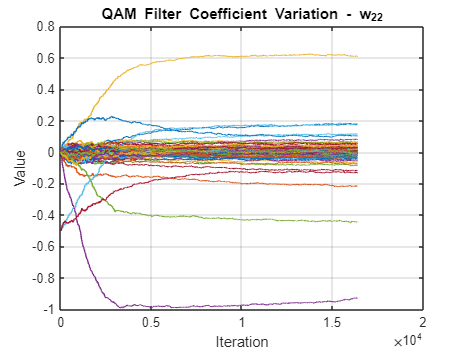

title("QAM Filter Coefficient Variation - w_{22}")
xlabel("Iteration")
ylabel("Value")
grid on


plot([1:size(pQAM)], pQAM, '-');

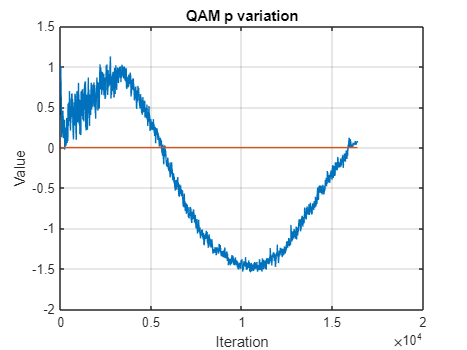

title("QAM p variation")
xlabel("Iteration")
ylabel("Value")
grid on

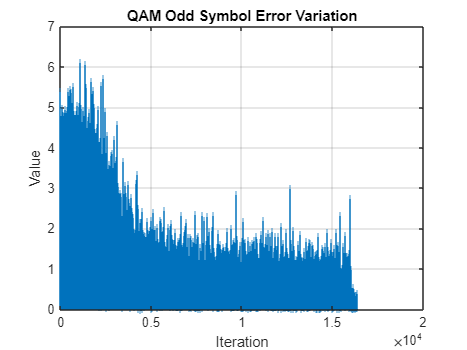


stem([1:size(errQAM(:,1))], abs(errQAM(:,1)), '|');
title("QAM Odd Symbol Error Variation")
xlabel("Iteration")
ylabel("Value")
grid on

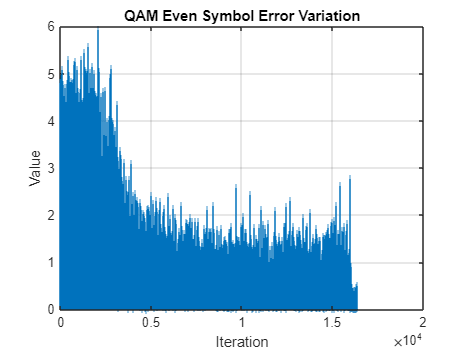


stem([1:size(errQAM(:,2))], abs(errQAM(:,2)), '|');
title("QAM Even Symbol Error Variation")
xlabel("Iteration")
ylabel("Value")
grid on

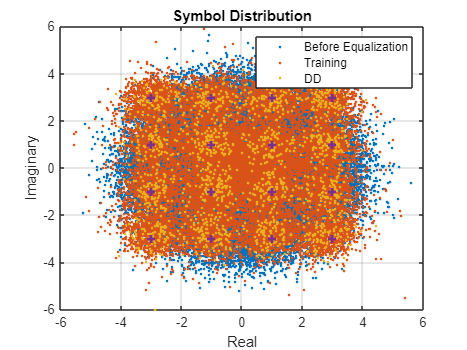


plot(signal_CDC, '.');
hold on
title("Symbol Distribution")
plot(equalizedSymbs(1:NRemoveF), '.');
plot(equalizedSymbs(NRemoveF+1:end-NRemoveB), '.');
plot(s_qam, '+', LineWidth=2);
xlabel("Real")
ylabel("Imaginary")
legend("Before Equalization", "Training", "DD")
grid on
hold off

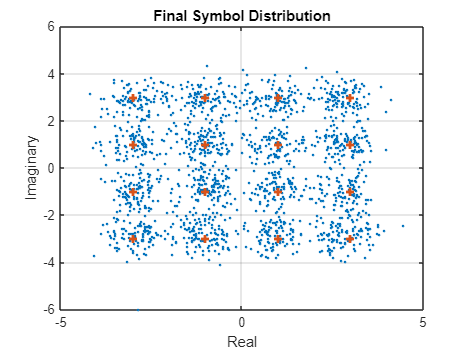


plot(equalizedSymbs(NRemoveF+1:end-NRemoveB), '.');
hold on
plot(s_qam, '+', LineWidth=2);
title("Final Symbol Distribution")
xlabel("Real")
ylabel("Imaginary")
grid on
hold off

% Decision and decoding

sourceInts = qamdemod(s_qam(NRemoveF+1:end-NRemoveB,1), 16);
sourceBits = int2bit(sourceInts, 4);

EqualizedInts = qamdemod(equalizedSymbs(NRemoveF+1:end-NRemoveB,1), 16);
EqualizedBits = int2bit(EqualizedInts, 4);

[~, BER] = biterr(sourceBits, EqualizedBits)

BER = 0.0185